
fig = figure;
%Prompts to get informtaion:
prompt = {'How many times should the calculations iterate over?','display diagnostic information (1 for yes, 0 for no.)?'};
dlgtitle = 'Iterations';
dims = [1, 35];
definput = {'1','0'};
answer = inputdlg(prompt,dlgtitle,dims,definput);
%Catching Potenital Errors
catchError(answer,definput)

%extracting information from first prompt:
maxIterations = str2double(answer);
debug = maxIterations(2);
maxIterations = maxIterations(1);

%Second Prompt:
prompt = {'age','height','weight','Gender? (0 for male, 1 for female','opiates? (0 for no opiates present in the system, 1 for opiates in the system.)'};
dlgtitle = 'Specifications';
dims = [1, 35];
definput = {'35','170','70','0','0'};
%Extracting:
answer = inputdlg(prompt,dlgtitle,dims,definput);
catchError(answer,definput)
answer = str2double(answer);
age = answer(1);
weight = answer(3);
height = answer(2);
BMI = weight/((height/100)^2);
genderBool = answer(4);
opiatesBool = answer(5);

%If chosen to display dignostic information, here is where it is printed:
if(debug)
disp("Age: " + age + "yrs" + "Weight: "+ weight + "kg" + "Height: "+ height + "cm")
disp("BMI: " + BMI)
end

%Where the input function is defined
prompt = {'How long will the simulation last? (in min)','Does your input function change at different intervals? (1 for yes, 0 for no)','If not, define your function below (in terms of x and in mg/(kg*min) please):'};
dlgtitle = 'Function and Time Specifications';
dims = [1, 35];
definput = {'1000','0','0.2'};
%Extracting:
answer = inputdlg(prompt,dlgtitle,dims,definput);
catchError(answer,definput)
answerNum = str2double(answer);

curTime = 0;
%Time values used in ode45 and as t values in input function calculations
timeVector = linspace(1, answerNum(1),300);
%Function to make the time vector usable within ode45 simulation
%calculations
setTimeVec(timeVector)
%Setting input function as a sym structure and checking for errors:
answerFunc = str2sym(answer);
try
    syms f(x)
    f(x) = answerFunc(3);
    inputNumbers = double(f(1));
catch ME
    error('Error in formulation of sym structure based on given function. You likely did not put your function in terms of x.')
end
%Loop for multiple input functions
if(answerNum(2))
    %Bool is redefined every iteration by the user to decide whether or not
    %to continue inputting functions.
    bool = 1;
    timeIntervals = [];
    Functions = [];
    lastTime = 0;

    while(bool&&(curTime<answerNum(1)))
        prompt = {'How long will this function be the input for? (in min)','Define the input during this time below (again, in terms of x and in mg/(kg*min) please):','To end, type 0 in this box.'};
        dlgtitle = 'Function and Time Specifications 2: Electric Bogaloo';
        dims = [1, 35];
        definput = {'1000','0','1'};
        Answer = inputdlg(prompt,dlgtitle,dims,definput);
        %Error catching:
        catchError(Answer,definput)
        %Casting the user input as first a double array and then a sym
        %structure:
        answerDbl =  str2double(Answer);
        answerSym = str2sym(Answer);
        bool = answerDbl(3);
        %Catching errors:
        try
            syms f(x)
            f(x) = answerSym(2);
            inputNumbers = double(f(1));
        catch ME
            error('Error in formulation of sym structure based on given function. You likely did not put your function in terms of x.')
        end
        %counting time so the while loop knows when the alloted time for
        %the simulation has passed (further checking is done on line 102-104 for changing functions)
        curTime = lastTime+answerDbl(1);
        %concatenating previous functions and time intervals with the next
        %interval and matching function:
        timeIntervals = cat(1,timeIntervals,curTime);
        Functions = cat(1,Functions,answerSym(2))

        lastTime = curTime;
        prompt = {'Repeat at this interval with 0 mg/(kg*min) intervals with the entered function? 1 for yes, 0 for no'};
        dlgtitle = 'Function and Time Specifications 2: Electric Bogaloo';
        dims = [1, 35];
        definput = {'0'};
        Answer = inputdlg(prompt,dlgtitle,dims,definput)
        bool2 = str2double(Answer)
        if(bool2)
            bool = false;
            timeInt = answerDbl(1);
            bool3 = true;
            while(timeIntervals(length(timeIntervals))<answerNum(1))
                timeIntervals = cat(1,timeIntervals,timeInt+timeIntervals(end));
                if(bool3)
                    Functions = cat(1,Functions,0)
                    bool3 = false;
                else
                    Functions = cat(1,Functions,answerSym(2))
                    bool3 = true;
                end
            end
        end
    end
    if(timeIntervals(length(timeIntervals))~=answerNum(1))
        warning('Your intervals for each function definition do not sum to the total time chosen to simulate for. The final function definition will either be shortened or lengthened to match the total time chosen to simulate for.')
        timeIntervals(end) = timeVector(end);
    end
        %defining necessary variables, where i and p are iterators and
        %inputFinalVector is a vector of input function inputs over time:
        inputFinalVector = [];
        i=1;
        p=1;
        
        %for loop to get input vector:
        for w=1:length(Functions)
            input = [];
            %while loop to count the intervals to the next function
            %definition
            while(timeVector(i)<timeIntervals(w))
                i=i+1;
            end
            %using the sym structure to get inputs:
            syms f(x)
            f(x) = Functions(w);
            
            for j=p:i
                inputNum = double(f(timeVector(j)));
                input = cat(1,input,inputNum);
            end

            %concatenating each segment of input function with the next and
            %so on.
            inputFinalVector = cat(1,inputFinalVector,input);
            %redefining p to start where the last input function ended:
            p=length(inputFinalVector);
        end
    %setting all of the gained information to be availible to ode45 during
    %the simulation
    setTime_setFunction(timeIntervals,inputFinalVector)
    %for an input function that does not change its definition over time:
    
else
    timeIntervals = answerNum(1);
    syms f(x)
    f(x) = answerFunc(3);
    inputNumbers = double(f(timeVector));
    %setting all information as availible to ode45 during its simulation
    setTime_setFunction(answerNum(1),inputNumbers);
    inputFinalVector = inputNumbers;
end

$$Functions = 0.2$$

Answer = 1×1 cell array
    {'1'}


bool2 = 1

$$Functions = \left(\begin{array}{c} 0.2\\ 0 \end{array}\right)$$

%error catching and adjusting
if(timeIntervals(length(timeIntervals))~=answerNum(1))
    warning('Your intervals for each function definition do not sum to the total time chosen to simulate for. The final function definition will either be shortened or lengthened to match the total time chosen to simulate for.')
    timeIntervals(end) = timeVector(end);
end

%Estimated Model Parameters
theta1 = 6.28;
theta2 = 25.5;
theta3 = 273;
theta4 = 1.79;
theta5 = 1.75;
theta6 = 1.11;
theta7 = 0.191;
theta8 = 42.3;
theta9 = 9.06;
theta10 = -0.0156;
theta11 = -0.00286;
theta12 = 33.6;
theta13 = -0.0138;
theta14 = 68.3;
theta15 = 2.10;
theta16 = 1.30;
theta17 = 1.42;
theta18 = 0.68;
%reference variables
age_ref = 35;
height_ref = 170;
weight_ref = 70;
BMI_ref = 24.2;
%for loop for # of trials
avg = transpose([zeros(size(timeVector));zeros(size(timeVector));zeros(size(timeVector));zeros(size(timeVector))]);
coeffavg = zeros(1,8);
for i=1:maxIterations

%C1 is dependent on gender
if(genderBool)
    C1 = theta15;
    gender = "female";
else
    C1 = theta4;
    gender = "male";
end
%displays patient information
if(debug)
    disp("Trial: " + i)
    disp("gender: "+gender)
    if(opiatesBool)
        disp("Opiates present in patient's system")
    else
        disp("Opiates not present in patient's system")
    end
end
%calculates information, two versions, one for displaying to the console
%one for not:
a = 0.01;
b = 0.5;

    disp("gender: "+gender)
    if(opiatesBool)
        disp("Opiates present in patient's system")
    else
        disp("Opiates not present in patient's system")
    end


PMA = age*52+40;
e = exp(1);
if(opiatesBool)
    opiatesCL = e^(theta11*age);
    opiatesV3 = e^(theta13*age);
else
    opiatesCL = 1;
    opiatesV3 = 1;
end
V1 = theta1*(f_central(weight)/f_central(weight_ref))*e^(rand());
V2 = theta2*(weight/weight_ref)*f_ageing(theta10,age)*e^(rand());
if(genderBool)
    coeffCL = theta15;
    Al_Sallami = (1.11+((1-1.11)/(1+(age/7.1)^-1.1)))*9270*weight/(8780+244*BMI);
else
    coeffCL = theta4;
    Al_Sallami = (0.88+((1-0.88)/(1+(age/13.4)^-12.7)))*9270*weight/(6680+216*BMI);
end
%{
Al_Sallami_ref = (0.88+((1-0.88)/(1+(age_ref/13.4)^-12.7)))*9270*weight_ref/(6680+216*BMI_ref);
V3 = theta3*(Al_Sallami/Al_Sallami_ref)*opiatesV3*exp(rand());
CL = coeffCL*(weight/weight_ref)^0.75*(CL_maturation(PMA)/CL_maturation(age_ref*52+40))*opiatesCL*e^(rand());
V2_ref = 25.5;
Q3mat = fQ3_maturation(age)
Q3mat_ref = fQ3_maturation(age_ref)
Q2 = theta5*(V2/V2_ref)^(0.75)*(1+theta16*(1-Q3mat))*e^(rand());
V3_ref = 273;
Q3 = theta6*(V3/V3_ref)^0.75*(Q3mat/Q3mat_ref)*e^(rand());
%}
%Calculating coeffciients for Schnider's model:
theta1_Schn = 4.27;
theta2_Schn = 18.9;
theta3_Schn = 238;
theta4_Schn = 1.89;
theta5_Schn = 1.29;
theta6_Schn = 0.836;
theta7_Schn = -0.391;
theta8_Schn = 0.0456;
theta9_Schn = -0.0681;
theta10_Schn = 0.0264;
theta11_Schn = -0.024;
%W.P.T. James' LBM equation
LBM = 1.1*weight-128*((weight/height)^2);
%Volumes (L)
V1_Schn = theta1_Schn;
V2_Schn = theta2_Schn + theta7_Schn*(age-53);
V3_Schn = theta3_Schn;

%Clearances(L/min)
C1_Schn = theta4_Schn + theta8_Schn*(weight-77)+(LBM-59)*theta9_Schn+(height-177)*theta10_Schn;
C2_Schn = theta5_Schn + theta11_Schn*(age-53);
C3_Schn = theta6_Schn;

k_10 = 0.443 + 0.0107*(weight-77)-0.0159*(LBM-59) + 0.0062*(height-177);
k12 = 0.302 - 0.0056*(age - 53);
k13 = 0.196;
k21 = (1.29 - 0.024*(age - 53))/(18.9 - 0.391*(age -53));
k31 = 0.0035;
CL_Schn = k_10+k12+k13;


%setting Eleveld coefficients as global variables to be used by ode45:
%Companion File:
PKPDGUI2companion
z = [V1,V2,V3,CL,Q2,Q3,weight,ke_0];
setCoefficients([V1,V2,V3,CL,Q2,Q3,weight,ke_0]);
if(1)
    disp(z)
end
%running ode45:


[t,y] = ode45(@vdp1,timeVector,[0; 0; 0; 0]);

%plotting, random colors with a static R in RGB so the average, which is
%red, will stand out more.
subplot(3,1,1);
plot(t,y,'Color',[211/255,211/255,211/255])
xlabel('Time (min)')

title('Propofol Concentration over Time (Eleveld Model)')
hold on;

%getting sum of all inputs for averaging:
avg = avg + y;
coeffavg = coeffavg + z;
end

gender: male


Opiates not present in patient's system


BMI = 24.2215

BMI_ref = 24.2215

V1 = 8.7921

V2 = 29.3015

V3 = 548.9265

CL = 0.5322

Q3mat = 0.9646

Q3mat_ref = 0.9646

Q2 = 2.6304

Q3 = 1.9702

ke_0 = 0.1812

worked2
Straight from the Research Document
   1.0e+03 *

    1.0792    0.9192    0.7842    0.9582    0.7842



RV1 = 0.6757

CV1 = 0.6757

M1 = 1

KV2 = 1

MCL = 1.0000

RCL = 1.0000

DCL = 1

PMEW = 1860

PMER = 1860

Straight from the R model
  695.0339  535.0339  400.0339  574.0339  400.0339



    6.2830   25.5010  168.3089    5.4189    1.7500    0.7720   70.0000    0.2056



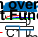

avg = avg/maxIterations;
coeffavg = coeffavg/maxIterations;
p1 = plot(t,avg(:,1),'r');
p2 = plot(t,avg(:,2),'b');
p3 = plot(t,avg(:,3),'g');
p4 = plot(t,avg(:,4),'p');
legend([p1(1),p2(1),p3(1),p4(1)],{'Average in C1','Average in C2','Average in C3','Avg in Effect Site Compartment'})

hold off;
EleveldK_eoHolder = y(:,4);
%setting Schnider's coefficients as global variables to be used by ode45:
setCoefficients([V1_Schn,V2_Schn,V3_Schn,C1_Schn,C2_Schn,C3_Schn,weight,0.456]);
[t,y] = ode45(@vdp1,timeVector,[0; 0; 0; 0]);
subplot(3,1,2)
hold on;
p1 = plot(t,y(:,1),'r');
p2 = plot(t,y(:,2),'b');
p3 = plot(t,y(:,3),'g');
legend([p1(1),p2(1),p3(1)],{'C1','C2','C3'})
hold off;
xlabel('Time (min)')
ylabel('Propofol Concentration (mcg/mL)', fontsize = 8)
title('Propofol Concentration over Time (Schnider Model)')


%plotting input function
subplot(3,1,3);
plot(timeVector,(inputFinalVector(1:length(timeVector))))
xlabel("Time (min)")
ylabel("Dosage (mg/kg)", fontsize = 9)
title("Input Function")

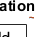


figure;
p = plot(t,[avg(:,4),y(:,4)]);
xlabel('Time (min)')
ylabel('Propofol Concentration (mcg/mL)', fontsize = 8)
title('Effect Compartment Concentration Over Time (Eleveld and Schnider)')
lg = legend([p(1),p(2)],{'Eleveld','Schnider'});
lg.FontSize = 10;

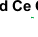


figure;
hold on;
p2 = plot(t,y(:,2),'b');
p3 = plot(t,y(:,4),'g');
title('Cp and Ce Over Time')
xlabel('Time (min)')
ylabel('Propofol Concentration (mcg/mL)')
hold off;

%Code for potentially plotting at 15 second intervals
%{
timn = []
counter = 1;
vectorr=[];


for b=1:length(y(:,2))
   
    if(counter<timeVector(b))
         timn = cat(1,timn,b);
        vectorr = cat(1,vectorr,avg(2,b));
        counter = counter+0.25;
    end
end
figure;
plot(timn, vectorr)
xlabel('Time (15 second intervals)')
ylabel('Propofol Concentration (mcg/mL)')%}
%}

Functions

function f1 = f_ageing(x,age) 
e = exp(1);
age_ref = 35;
f1 = e^(x*(age-age_ref));
end
function f2 = f_sigmoid(x,E50,lambda)
f2 = (x^(lambda))/(x^(lambda)+E50^(lambda));
end
function f3 = f_central(x)
theta12 = 33.6; 
f3 = f_sigmoid(x,theta12,1);
end
function f3 = CL_maturation(PMA)
theta8 = 42.3;
theta9 = 9.06;
f3 = f_sigmoid(PMA,theta8,theta9);
end
function f4 = fQ3_maturation(age)
theta14 = 68.3;
f4 = f_sigmoid(age*52+40,theta14,1);
end
%ode45 function
function dydt = vdp1(t,y)
%getting information and setting variables
vectorParam = getCoefficients();
V_10 = vectorParam(1);
V_20 = vectorParam(2);
V_30 = vectorParam(3);
CL0 = vectorParam(4);
Q_20 = vectorParam(5);
Q_30 = vectorParam(6);
weight = vectorParam(7);
ke_0 = vectorParam(8);
func = getFunction();
timeVec = getTimeVec();
%getting value of the input at time t:
w=1;

    while(timeVec(w)<t)
        w=w+1;
    end

inputNum = func(w);

%Eleveld PK model implementation (three-compartment mammillary system with well defined
%coefficients)
dydt = [(-(3*CL0/V_10))*(y(1))+(Q_20/V_10)*(y(2))+(Q_30/V_10)*y(3)+(inputNum)*(weight/V_10); ((CL0/V_20)*y(1)-(Q_20/V_20)*y(2));((CL0/V_30)*y(1)-(Q_30/V_30)*y(3));ke_0*(y(1)-y(4))];
end
%setting values as global variables for usage in ode45:
function setCoefficients(vctr)
global V1
V1 = vctr(1);
global V2 
V2 = vctr(2);
global V3
V3 = vctr(3);
global CL 
CL = vctr(4);
global Q2
Q2 = vctr(5);
global Q3 
Q3 = vctr(6);
global patWeight
patWeight = vctr(7);
global ke_0 
ke_0 = vctr(8);
end
function f = getCoefficients
global V1
global V2
global V3
global CL
global Q2
global Q3
global patWeight
global ke_0
f = [V1,V2,V3,CL,Q2,Q3,patWeight,ke_0];
end
function setTime_setFunction(tvctr,fvctr)
global functionDef
functionDef = fvctr;
global timeIntervalDef
timeIntervalDef = tvctr;
end
function g = getFunction
global functionDef
g = functionDef;
end
function h = getTime
global timeIntervalDef
h = timeIntervalDef;
end
function setTimeVec(timeVctrr)
global timeVectorr
timeVectorr = timeVctrr;
end
function j = getTimeVec
global timeVectorr
j = timeVectorr;
end
%catching potential errors:
function catchError(answer,defInput)
for i=1:length(defInput)
    try
        c = answer(i);
    catch ME
        error('Certain fields remained undefined, please properly define each field or leave the inputs as their defaults. It may also be the case you have canceled the process by closing the input window, in which case you will have to rerun the program.')
    end
end
end